# MATLAB-Python Workflow to Convert SMILES to Molecular Graph   

### Introduction

This simple example demonstrates how [Python-MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) can work together for molecular structure processing. Using a single molecule input, we are illustrating the construction of a high throughput workflow that process [SMILES](https://en.wikipedia.org/wiki/Simplified_molecular-input_line-entry_system) database and generates mathematical [graph](https://www.mathworks.com/help/matlab/ref/graph.html) objects that can be then fed into graph neural networks to perform other predictive tasks.  

### RDKit Installation

This example uses some of the fucntions from [RDKit](https://www.rdkit.org/) [1]. RDKit can be installed easily by following its [istallation](https://www.rdkit.org/docs/Install.html) instructions on Linux, Windows, and macOS. You can install RDKit using pip. Make sure to give the python addess and to check versions of Python compatible with MATLAB products by release. This allows to build proper [MATLAB Interface to Python](https://www.mathworks.com/support/requirements/python-compatibility.html).

clear;
clc;
close all;
warning('off','all')
pyenv("Version","C:\Users\...\my-rdkit-env\python.exe");


### Input molecule and substructure

Provide the SMILES sting. You can also provide the substructure you would like to highlight in the molecule.

SMILES="CCCC(=O)OC[C@@H]1CC[C@H](n2cnc3c(=O)nc[nH]c32)O1";
Substr="CCCC(=O)";

### Draw molecules and highlight substructures

The following Python functions construct a molecule object from the given SMILES string. See the examples on [this page](https://www.rdkit.org/docs/GettingStartedInPython.html) to get started with the RDKit in Python.

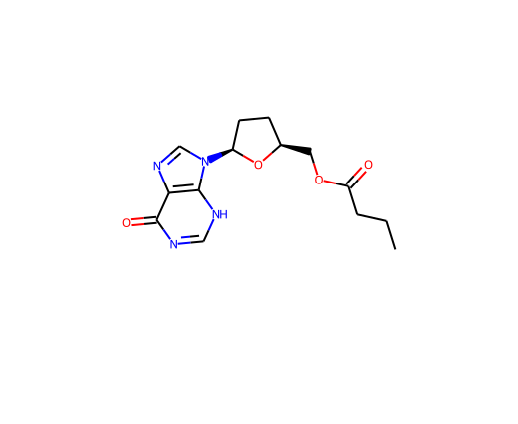

res0 = pyrunfile("ChemMolFromSmiles.py","mol0",x=SMILES);
img0 = string(res0);
rgbImage0 = imread(img0);
imshow(rgbImage0)

The following Python function returns the highlighted substructure string (Substr).

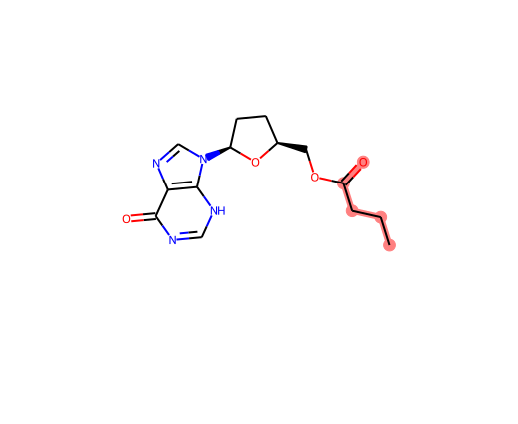

res1 = pyrunfile("GetSubstructMatch.py","mol1",x=SMILES,y=Substr);
img1 = string(res1);
rgbImage1 = imread(img1);
imshow(rgbImage1)

### Construct adjacency matrix for molecular graph

We now convert the generated molecule object to pdb block. This allows us to easily use the `CONECT` records to construct the adjacency matric of the molecular graph object in MATLAB. Make sure that set the path correctly (in the python file) that the generated pdb file is stored. The generate pdb file can be visualised using [molviewer](https://www.mathworks.com/help/bioinfo/ref/molviewer.html) (requires Bioinformatics toolbox)

pdbout = pyrunfile("MolToPDBBlock.py","molpdb",x=SMILES);

<string>
.


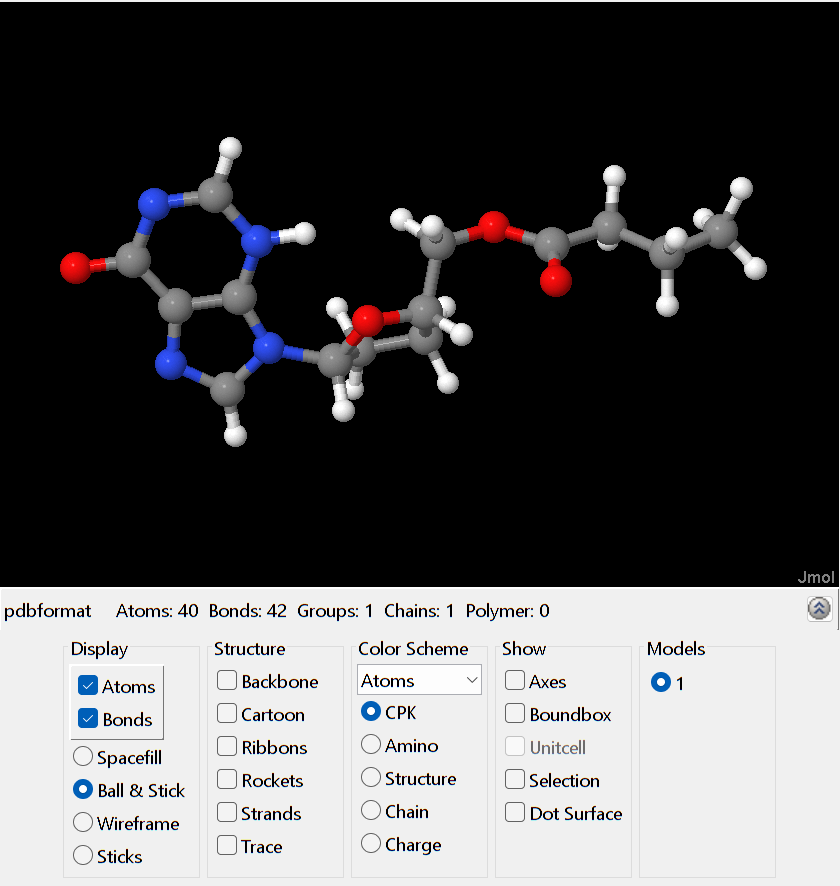

pdbfile = string(pdbout);
molviewer(pdbfile)

This MATLAB function reads the pdb file and constructs the corresponding adjacency matrix.

Adj = pdbToADJ(pdbfile);
Adjmat = Adj;

When molecule consists of less than certain number of atoms, there will be padded zeros. Remove any padded zeros. Remove padded zeros from the data, i.e. make it a square matrix the size

NumAtoms = pyrunfile("GetNumAtoms.py","numatom",x=SMILES);
NumAtm=int64(NumAtoms);
padAdj = Adjmat(1:NumAtm, 1:NumAtm);

### Construct node feature matrix for molecular graph

The following function extract seven atomic features from the above given SMILES structure. The node/feature matrix includes: *atomic number*, *atomic mass*, *total atomic valance*, *atomic degree*, *number of hydrogens connected to the atom*, *atomic hybridization (“sp”, “sp2”, “sp3”)*, and whether the atom belongs to an *aromatic ring*. 

NodeData = pyrunfile("GetNodeFeaturesMatrix.py","nodedat",x=SMILES);
Nodefile = string(NodeData);
nodefeat = dlmread('NodeFeaturesMatrix.dat');
nodesym = nodefeat(1:size(NumAtm,1));
nodesym = nodefeat(:);

### Visualize molecular graph

Now that we have both the adjacency and feature matrices, we can use MATLAB graph function to build the moecular graph and plot it.

save('graph_data.mat',"padAdj","nodefeat");

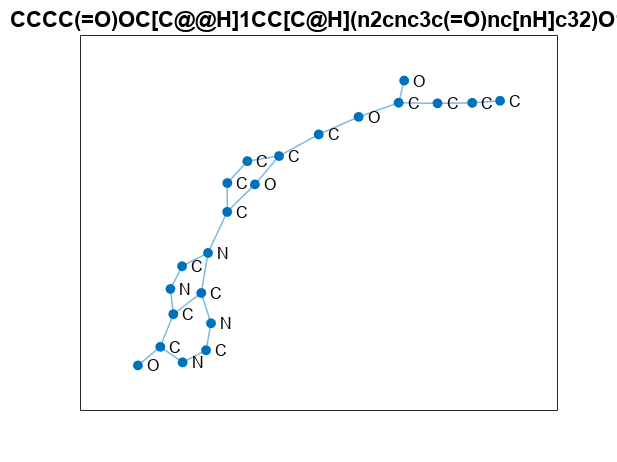

atomsymbols = Symbols(nodesym,NumAtm);
compound = graph(padAdj);
figure, plot(compound, 'NodeLabel', atomsymbols, 'LineWidth', 0.75, 'Layout','force')
title(SMILES)

We can now use Matlab's multiple built-in [Graph and Network Algorithms](https://www.mathworks.com/help/matlab/graph-and-network-algorithms.html?s_tid=CRUX_lftnav) for graph strucure analysis. For example, in the next live script we will look at how graph Laplacian eigenvectors are used as Transformer positional encodings (PE).

### References

[1] RDKit: Open-source cheminformatics; [http://www.rdkit.org](https://www.rdkit.org/)